# Exercise 1.2 - Generating musical tones

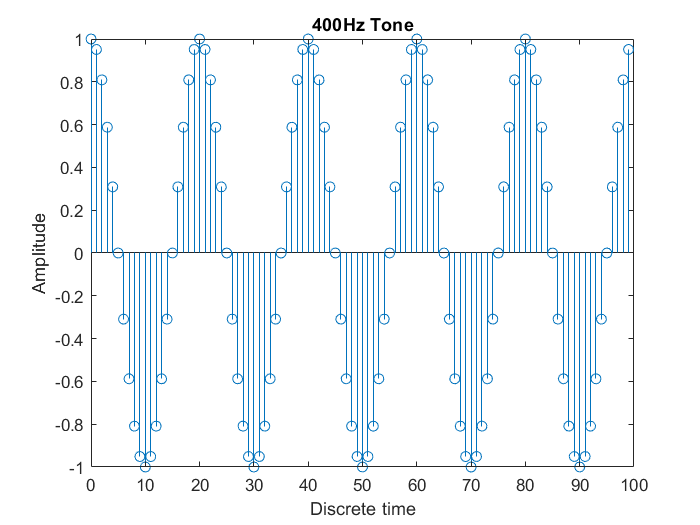

% Let's generate a signal; a musical tone of 400 Hz. We shall use a sampling 
% frequency of 8 kHz and have a duration of 1 s (meaning that we need a 
% total of 8000 samples). We will employ the wave equation for this purpose.
fs = 8000; 
n = 0 : fs - 1;
x = cos(2 * pi * 400 * n / fs); 
 
% Play the tone.
sound(x, fs); 
 
% Plot a fragment of 100 samples in the discrete-time domain.
x100 = x(1 : 100); n100 = n(1 : 100);
stem(n100, x100)
xlabel('Discrete time'), ylabel('Amplitude')
title('400Hz Tone')

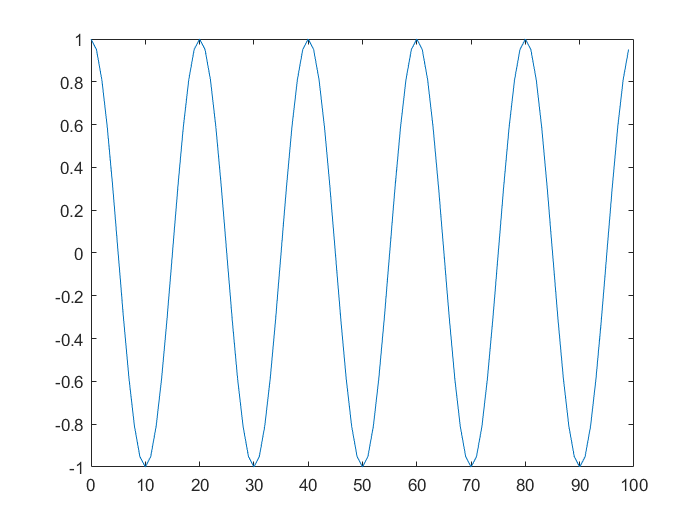


% Let's plot that same fragment in the continuous-time domain.
plot(n100, x100);

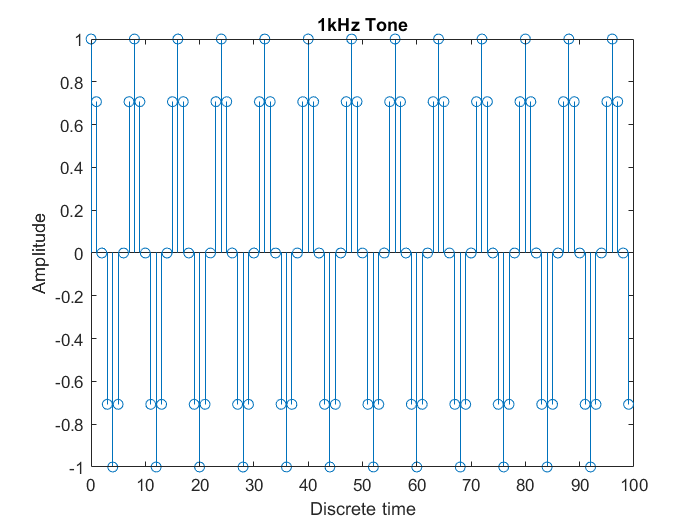

xlabel('Continuous time'), ylabel('Amplitude')
title('400Hz Tone')

% Analogously, let's generate, play and plot a �1kHz tone�. Note how the
% frequency changes in the wave equation.
x1 = cos(2 * pi * 1000 * n / fs);
sound(x1, fs);
x1_100 = x1(1 : 100);
stem(n100, x1_100)
xlabel('Discrete time'), ylabel('Amplitude')
title('1kHz Tone')

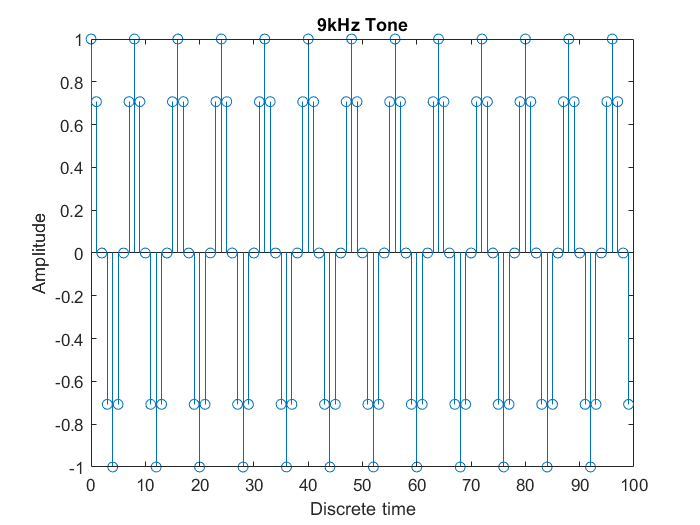


% Let's do one more example; a 9 kHz tone�. Play close attention to the
% output of this last plot. Notice anything strange in relation to the
% others? Check the observations below for a detailed explanation of 
% what's going on here.
x2 = cos(2 * pi * 9000 * n / fs);
sound(x2, fs);
x2_100 = x2(1 : 100);
stem(n100, x2_100)
xlabel('Discrete time'), ylabel('Amplitude')
title('9kHz Tone')

## Observations

Despite having an analog frequency that is 9 times that of the previous signal, when plotting, we see that they are one and the same. In fact, if we play both tones, they sound identical. We are faced with a case of aliasing. This is due to the signal being sampled below its Nyquist frequency. Its digital frequency is f�d� = f�a� / f�s� = 9 / 8 (dimensionless). Since f�d� > 1 / 2, the resulting frequency is f_�alias �= 9 / 8 - 1 = 1 / 8. Thus, we have f�a_alias� = 1 kHz, which is the analog frequency counterpart of the tone.